# Laboratorio di Automatica (Prova del 07 Luglio 2020)

Riccardo Antonello ([antonello@dei.unipd.it](mail:antonello@dei.unipd.it)) and Luca Schenato ([schenato@dei.unipd.it](mail:schenato@dei.unipd.it)) 

July 07, 2020

Dept. of Information Engineering, University of Padova

## Esercizio 2

Si consideri il sistema di controllo di velocità a tempo discreto per un motore elettrico in corrente continua illustrato in Fig. 2a, dove:

- $P(z)$ è la funzione di trasferimento del motore, da ingresso in tensione $u$ $[V]$ ad uscita in posizione $\vartheta$ $[\mathrm{rad}]$, ottenuta discretizzando, *con il metodo esatto*, il seguente modello a tempo continuo:


$$P(s) = \frac{\Theta(s)}{U(s)} = \frac{k_m}{s(T_m\,s + 1)} \quad \text{con} \quad k_m = 5.2\,,\quad T_m = 0.03$$
  

- $C(z)$ è la funzione di trasferimento del controllore, con ingresso l'errore di velocità $e\,\mathrm{[rad/s]}$ ed uscita la tensione di comando $u_C\,[\mathrm{V}]$, ottenuta discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, il seguente controllore PD (con derivata reale) a tempo continuo:


$$C(s) =\frac{U_C(s)}{E(s)} = K_P \,+\, \frac{K_D\,s }{T_L\,s + 1}
\quad\text{con}\quad
K_P = 0.472\,,\quad
K_D=0.016\,,\quad
T_L=0.004$$


- $H(z)$ è la funzione di trasferimento di un filtro "derivata reale" utilizzato per ricavare una stima $\omega\,\mathrm{[rad/s]$ della velocità del motore a partire dalla misura di posizione $\vartheta\,[\mathrm{rad}]$; è ottenuta discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, il seguente filtro a tempo continuo:


$$H(s) = \frac{\Omega(s)}{\Theta(s)} = \frac{\omega_c^2\,s}{s^2 + 2 \delta \omega_c s + \omega_c^2}
\quad\text{con}\quad
\omega_c = 2 \pi\,5\,\mathrm{rad/s},\,\quad
\delta=\frac{1}{\sqrt{2}}$$


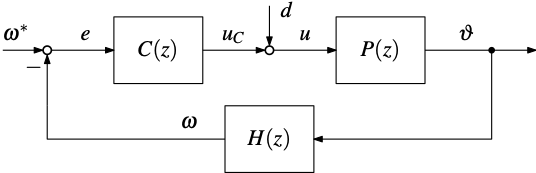

(a)

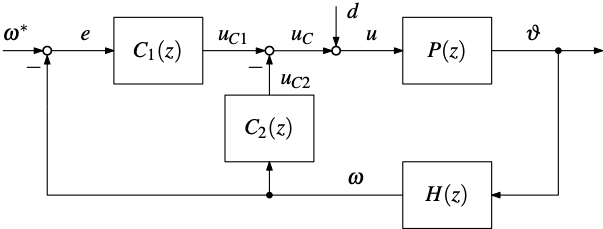

(b)

**Figura 2**: Sistema di controllo di velocità a tempo discreto: (a) ad un grado di libertà; (b) a due gradi di libertà.

Considerando un periodo di campionamento pari a $T_s=0.01,\mathrm{s}$, ed utilizzando *esclusivamente* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Ricavare le seguenti funzioni di trasferimento:

- $T_1(z)=\Omega(z)/\Omega^*(z)$ da riferimento di velocità $\omega^*$ a misura di velocità $\omega$.

- $G_1(z)=\Omega(z)/D(z)$ da disturbo di carico $d$ a misura di velocità $\omega$.

- $W_1(z)=U(z)/\Omega^*(z)$ da riferimento di velocità $\omega^*$ a comando in tensione $u$.

*Soluzione*.

%   plant tf
km = 5.2;
Tm = 0.03;
sysP = tf(km, [Tm, 1, 0]);

Ts = 0.01;
sysP = c2d(sysP, Ts, 'zoh');

%   speed filter tf
z = tf('z', Ts);
s = (z-1)/Ts/z;

wc = 2*pi*5;
d = 1/sqrt(2);
sysH = wc^2*s/(s^2 + 2*d*wc*s + wc^2);

%   PD controller tf
Kp = 0.472;
Kd = 0.016;
TL = 0.004;
sysC = Kp + Kd*s/(TL*s + 1);

%   closed-loop tf T1(z) (speed ref to speed meas)
sysT1 = minreal( sysC*sysP*sysH/(1 + sysC*sysP*sysH), 1e-5 );
zpk(sysT1)


ans =
 
        0.080351 z (z+0.8949) (z-0.7912)
  ---------------------------------------------
  (z-0.7846) (z-0.2204) (z^2 - 1.501z + 0.7675)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




%   closed-loop tf G1(z) (disturbance to speed meas)
sysG1 = minreal( sysP*sysH/(1 + sysC*sysP*sysH), 1e-5 );
zpk(sysG1)


ans =
 
        0.049757 z (z+0.8949) (z-0.2857)
  ---------------------------------------------
  (z-0.7846) (z-0.2204) (z^2 - 1.501z + 0.7675)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




%   closed-loop tf W1(z) (speed ref to command)
sysW1 = minreal( sysC/(1 + sysC*sysP*sysH), 1e-5 );
zpk(sysW1)


ans =
 
  1.6149 (z-0.7912) (z-0.7165) (z^2 - 1.584z + 0.6481)
  ----------------------------------------------------
     (z-0.7846) (z-0.2204) (z^2 - 1.501z + 0.7675)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



2) Mostrare (in tre figure MATLAB distinte) le seguenti risposte al gradino:

- velocità $\omega$$[\mathrm{rpm}]$ in risposta ad un riferimento a gradino di ampiezza $250\,\mathrm{rpm}$, applicato in $t=0$.

- velocità $\omega$$[\mathrm{rpm}]$ in risposta ad un disturbo di carico a gradino di ampiezza $3\,\mathrm{V}$, applicato in $t=0$.

- comando in tensione $u\,\mathrm{[V]}$ in risposta ad un riferimento a gradino di ampiezza $250\,\mathrm{rpm}$, applicato in $t=0$.

Nota: nel determinare le risposte, si faccia attenzione alle unità di misura.

*Soluzione*.

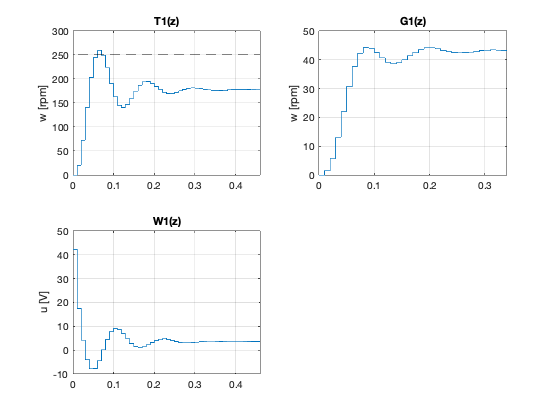

%   conversion gains
rads2rpm = 60/2/pi;
rpm2rads = 2*pi/60;

%   plot responses
figure; 
subplot(2,2,1); 
opt = stepDataOptions('StepAmplitude', 250*rpm2rads);
[w, t] = step(sysT1, opt);
stairs(t, w*rads2rpm);
hold on;
plot([0, t(end)], [250, 250], 'k--');
title('T1(z)');
ylabel('w [rpm]');
grid on;
xlim([0, t(end)]);

subplot(2,2,2); 
opt = stepDataOptions('StepAmplitude', 3);
[w, t] = step(sysG1, opt);
stairs(t, w*rads2rpm);
title('G1(z)');
ylabel('w [rpm]');
grid on;
xlim([0, t(end)]);

subplot(2,2,3); 
opt = stepDataOptions('StepAmplitude', 250*rpm2rads);
[u,t] = step(sysW1, opt);
stairs(t, u);
title('W1(z)');
ylabel('u [V]');
grid on;
xlim([0, t(end)]);

3) Si consideri lo schema di controllo alternativo mostrato in Fig. 2b, basato su un controllore in configurazione P-D (il termine derivativo D è posto sul ramo di retroazione, anzichè sul ramo diretto). I blocchi con funzioni di trasferimento $C_1(z)$ e $C_2(z)$ sono ottenuti discretizzando, *con il metodo di Eulero all'Indietro (Backward Euler)*, i seguenti controllori a tempo continuo:


$$C_1(s) =\frac{U_{C1}(s)}{E(s)} = K_P\,,
\qquad
C_2(s) = \frac{U_{C2}(s)}{\Omega(s)} = \frac{K_D s}{T_L s + 1}$$


In modo analogo a quanto proposto nel punto 1, si ricavino le funzioni di trasferimento $T_2(z)$ da velocità $\omega^*$ a misura di velocità $\omega$, $G_2(z)$ da disturbo di carico $d$ a misura di velocità $\omega$, e $W_2(z)$ da riferimento di velocità $\omega^*$ a comando in tensione $u$.

*Soluzione*.

%   P-D controller tf
sysC1 = Kp;
sysC2 = Kd*s/(TL*s + 1);

%   closed-loop tf T2(z) (speed ref to speed meas)
sysT2 = minreal( sysC1*sysP*sysH/(1 + (sysC1+sysC2)*sysP*sysH), 1e-5 );
zpk(sysT2)


ans =
 
        0.023485 z (z+0.8949) (z-0.2857)
  ---------------------------------------------
  (z-0.7846) (z-0.2204) (z^2 - 1.501z + 0.7675)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




%   closed-loop tf G2(z) (disturbance to speed meas)
sysG2 = minreal( sysP*sysH/(1 + (sysC1+sysC2)*sysP*sysH), 1e-5 );
zpk(sysG2)


ans =
 
        0.049757 z (z+0.8949) (z-0.2857)
  ---------------------------------------------
  (z-0.7846) (z-0.2204) (z^2 - 1.501z + 0.7675)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




%   closed-loop tf W2(z) (speed ref to command)
sysW2 = minreal( sysC1/(1 + (sysC1+sysC2)*sysP*sysH), 1e-5 );
zpk(sysW2)


ans =
 
  0.472 (z-0.7165) (z-0.2857) (z^2 - 1.584z + 0.6481)
  ---------------------------------------------------
     (z-0.7846) (z-0.2204) (z^2 - 1.501z + 0.7675)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



4) Ripetere quanto proposto nel punto 2, utilizzando le funzioni di trasferimento $T_2(z)$, $G_2(z)$ e $W_2(z)$ ottenute al punto precedente.

Verificare che la nuova configurazione di controllo P-D permette di evitare componenti impulsive sul comando $u$ a seguito dell'applicazione di segnali di riferimento $\omega^*$discontinui (tipo segnali di riferimento a gradino).

*Soluzione*.

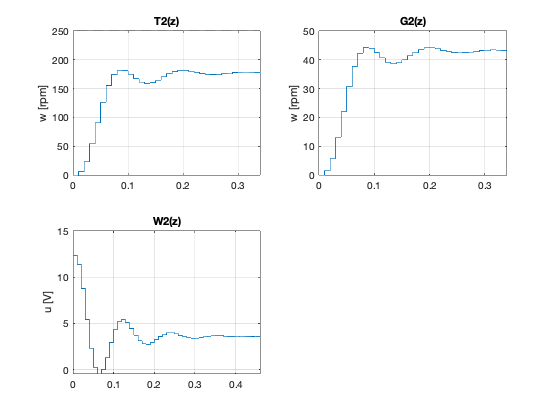

figure; 
subplot(2,2,1); 
opt = stepDataOptions('StepAmplitude', 250*rpm2rads);
[w, t] = step(sysT2, opt);
stairs(t, w*rads2rpm);
hold on;
plot([0, t(end)], [250, 250], 'k--');
title('T2(z)');
ylabel('w [rpm]');
grid on;
xlim([0, t(end)]);

subplot(2,2,2); 
opt = stepDataOptions('StepAmplitude', 3);
[w, t] = step(sysG2, opt);
stairs(t, w*rads2rpm);
title('G2(z)');
ylabel('w [rpm]');
grid on;
xlim([0, t(end)]);

subplot(2,2,3); 
opt = stepDataOptions('StepAmplitude', 250*rpm2rads);
[u,t] = step(sysW2, opt);
stairs(t, u);
title('W2(z)');
ylabel('u [V]');
grid on;
xlim([0, t(end)]);